# **Analyzing Neural Time Series Data**

*Theory and Practice: Mike X Cohen*

*Presented by: Armin Toghi*

*IDS Executive Member of Signal and Neuroimaging Department*

[armintoghi85@gmail.com](http://armintoghi85@gmail.com)

If you created two-dimensional (2-D) time-frequency power plots in previous chapters, you may have noticed that the plots were difficult to interpret visually because the magnitude of power changed considerably from the lowest frequency to the highest frequency, perhaps even by several orders of magnitude. The purpose of this chapter is to discuss methods for converting time-frequency power data to a scale that is amenable to qualitative visual inspection and quantitative statistical analysis.  

EEG time-frequency power obeys a 1/*f *phenomenon, the power at higher frequencies (e.g., gamma) has a much smaller magnitude than the power at lower frequencies (e.g., delta).  

figure

% 1/f function
c = 1;
x = 1;

plot(c./(1:100).^x)

The limitations of 1/f in interpreting the time frequency results

- It is difficult to visualize power across a large range of frequency bands.   

- It is difficult to make quantitative comparisons of power across frequency bands. You might want to determine, for example, whether the power increase in gamma is significantly bigger than the power decrease in alpha. Because the raw power values change in scale as a function of frequency,** lower frequencies will usually show a seemingly larger effect than higher frequencies** in terms of the overall magnitude.

- aggregating effects across subjects can be difficult with raw power values. This is because individual differences in raw power are influenced by skull thickness, sulcal anatomy, cortical surface area recruited, recording environment  

- taskrelated changes in power can be difficult to disentangle from background activity (this is also shown below). This is particularly the case for frequencies that generally tend to have higher power or frequencies that tend to have higher power during baseline periods, such as alpha activity over posterior parietal and occipital electrodes.   

- Raw power values are not normally distributed because they cannot be negative and they are strongly positively skewed. This limits the ability to apply parametric statistical analyses to time-frequency power data.  

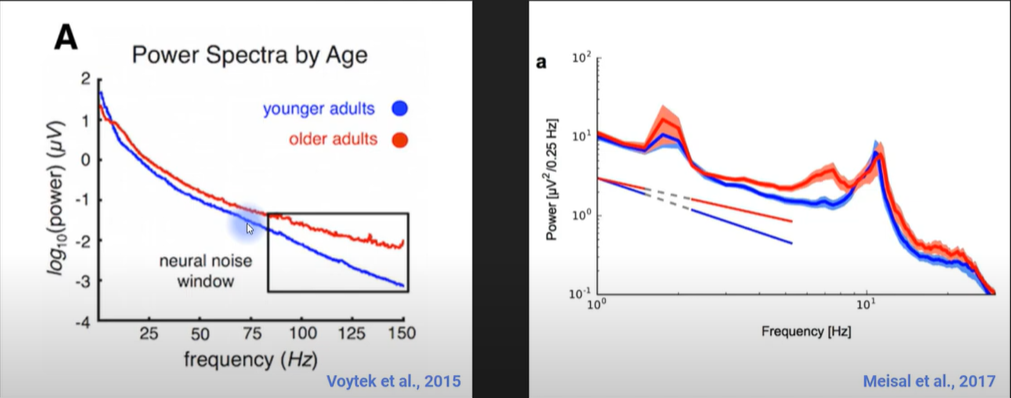

Time-frequency power plots showing that without any correction, no color scaling works optimally for all frequency bands. Taking the logarithm to base 10 of the data (log10; lower right panel) helps but does not fully eliminate the difference in scaling over frequencies. Furthermore, it is difficult to distinguish background (dynamics that do not change before and after time = 0) from task-related (dynamics that change as a function of stimulus onset) power.  

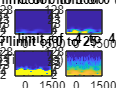


% load sample EEG data
load sampleEEGdata

% wavelet parameters
min_freq = 2;
max_freq = 128;
num_frex = 30;

% other wavelet parameters
frequencies = logspace(log10(min_freq),log10(max_freq),num_frex);
time = -1:1/EEG.srate:1;
half_of_wavelet_size = (length(time)-1)/2;

% FFT parameters (use next-power-of-2)
n_wavelet     = length(time);
n_data        = EEG.pnts;
n_convolution = n_wavelet+n_data-1;
n_conv_pow2   = pow2(nextpow2(n_convolution));
wavelet_cycles= 4; 

% FFT of data (note: this doesn't change on frequency iteration)
fft_data = fft(squeeze(EEG.data(23,:,1)),n_conv_pow2);

% initialize output time-frequency data
tf_data = zeros(length(frequencies),EEG.pnts);

for fi=1:length(frequencies)
    
    % create wavelet and get its FFT
    wavelet = (pi*frequencies(fi)*sqrt(pi))^-.5 * exp(2*1i*pi*frequencies(fi).*time) .* exp(-time.^2./(2*( wavelet_cycles /(2*pi*frequencies(fi)))^2))/frequencies(fi);
    fft_wavelet = fft(wavelet,n_conv_pow2);
    
    % run convolution
    convolution_result_fft = ifft(fft_wavelet.*fft_data,n_conv_pow2);
    convolution_result_fft = convolution_result_fft(1:n_convolution); % note: here we remove the extra points from the power-of-2 FFT
    convolution_result_fft = convolution_result_fft(half_of_wavelet_size+1:end-half_of_wavelet_size);
    
    % put power data into time-frequency matrix
    tf_data(fi,:) = abs(convolution_result_fft).^2;
end

% plot results
ytickskip = 2:4:num_frex; % This will be explained in the text.
figure
subplot(221)
imagesc(EEG.times,[],tf_data)
set(gca,'ytick',ytickskip,'yticklabel',round(frequencies(ytickskip)),'ydir','normal','xlim',[-500 1500],'clim',[0 5000])
xlabel('Time (ms)'), ylabel('Frequency (Hz)')
title('Color limit of 0 to 5000')

subplot(222)
imagesc(EEG.times,[],tf_data)
set(gca,'ytick',ytickskip,'yticklabel',round(frequencies(ytickskip)),'ydir','normal','xlim',[-500 1500],'clim',[0 800])
title('Color limit of 0 to 800')


subplot(223)
imagesc(EEG.times,[],tf_data)
set(gca,'ytick',ytickskip,'yticklabel',round(frequencies(ytickskip)),'ydir','normal','xlim',[-500 1500],'clim',[0 25])
title('Color limit of 0 to 25')

subplot(224)
imagesc(EEG.times,[],log10(tf_data))
set(gca,'ytick',ytickskip,'yticklabel',round(frequencies(ytickskip)),'ydir','normal','xlim',[-500 1500],'clim',[-4 4])
title('Color limit of -4 to 4 (log_1_0 units)')

### Baseline Normalization

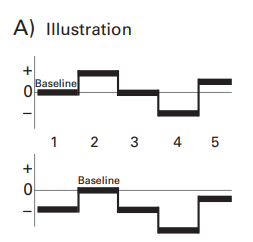

**Decibel Conversion** (for task-related): The decibel (dB) is a ratio between the strength of one signal (frequency-band-specific power) and the strength of another signal (a baseline level of power in that same frequency band). The decibel scale is convenient because it is robust to many limitations of raw power, such as 1/*f *power scaling and subject-specific and electrode-specific idiosyncratic characteristics. The base unit is called a bel and is the logarithm of a ratio of numbers.  

What is “the baseline”? The baseline is a period of time, typically a few hundred milliseconds before the start of the trial, when little or no task-related processing is expected.  

Typical decibel values after trial averaging are in the range of ±1 –4 dB. As is discussed below, for real data analyses, decibel conversion should be done on the trial-average power. That is, first average trials together and then transform to decibels; do not transform each trial to decibels separately and then average.  

% define baseline period
baselinetime = [ -500 -200 ]; % in ms

% convert baseline window time to indices
[~,baselineidx(1)]=min(abs(EEG.times-baselinetime(1)));
[~,baselineidx(2)]=min(abs(EEG.times-baselinetime(2)));

% dB-correct
baseline_power = mean(tf_data(:,baselineidx(1):baselineidx(2)),2);
dbconverted = 10*log10( bsxfun(@rdivide,tf_data,baseline_power));
% FYI: the following lines of code are equivalent to the previous line:
% dbconverted = 10*( bsxfun(@minus,log10(tf_data),log10(baseline_power)));
% dbconverted = 10*log10( tf_data ./ repmat(baseline_power,1,EEG.pnts) );
% dbconverted = 10*( log10(tf_data) - log10(repmat(baseline_power,1,EEG.pnts)) );

Error using contourf
Input arguments must have at most 2 dimensions.


figure
contourf(EEG.times,frequencies,dbconverted,40,'linecolor','none')
set(gca,'ytick',round(logspace(log10(frequencies(1)),log10(frequencies(end)),10)*100)/100,'yscale','log','xlim',[-500 1500],'clim',[-12 12])
title('Color limit of -12 to +12 dB')

time2plot = 300; % in ms

[~,timeidx] = min(abs(EEG.times-time2plot));

% plot frequencies
figure
subplot(211)
plot(frequencies,tf_data(:,timeidx))
title([ 'Power spectrum at ' num2str(EEG.times(timeidx)) ' ms' ])
ylabel('Raw power (\muV^2)')
xlabel('Frequency (Hz)')
 
subplot(212)
plot(frequencies,dbconverted(:,timeidx))
ylabel('Baseline-normalized power (dB)')
xlabel('Frequency (Hz)')


**Percentage Change and Baseline Division**  

Percentage change is another option for baseline normalization. Similar to decibels, after percentage change, the results must be interpreted as changes in power relative to the power during the baseline period.

  

***Z*****-Transform**  

With the *Z*-transform, power data are scaled to standard deviation units relative to the power data during the baseline period. The units are normal *Z *values and so can be easily interpreted and converted to *p *values (for example, *Z *= 1.96 corresponds to a two-tailed *p *= 0.05)  

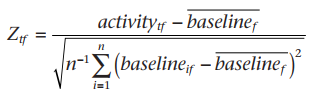

activity = 1:.01:20; % activity
baseline = 10; % baseline

db = 10*log10(activity./ baseline );
pc = 100*( activity-baseline)./ baseline;

figure
plot(db,pc)
xlabel('dB'), ylabel('Percent change')

% find indices where db is closest to -/+2
[~,dbOf2]=min(abs(db-2));
[~,dbOfminus2]=min(abs(db--2));

disp([ 'dB of -2 corresponds to ' num2str(pc(dbOfminus2)) '% change.' ])
disp([ 'dB of +2 corresponds to +' num2str(pc(dbOf2)) '% change.' ])

hold on
axislim=axis;
plot([db(dbOf2) db(dbOf2)],[pc(dbOf2) axislim(3)],'k',[axislim(1) db(dbOf2)],[pc(dbOf2) pc(dbOf2)],'k')
plot([db(dbOfminus2) db(dbOfminus2)],[pc(dbOfminus2) axislim(3)],'k',[axislim(1) db(dbOfminus2)],[pc(dbOfminus2) pc(dbOfminus2)],'k')

% real data: percent change vs. baseline division
figure
baseline_power = mean(tf_data(:,baselineidx(1):baselineidx(2)),2);
pctchange = 100 * (tf_data-repmat(baseline_power,1,EEG.pnts))./ repmat(baseline_power,1,EEG.pnts);
subplot(221)
baselinediv = tf_data ./ repmat(baseline_power,1,EEG.pnts);
plot(dbconverted(1:5:end),baselinediv(1:5:end),'.') % don't need all the datapoints to make a point
xlabel('DB'), ylabel('Baseline division')

% dB vs. baseline division
subplot(222)
plot(pctchange(1:5:end),baselinediv(1:5:end),'.')
xlabel('Percent change'), ylabel('Baseline division')

% Z-transform vs. percent change
subplot(223)
baseline_power = tf_data(:,baselineidx(1):baselineidx(2));
baselineZ = (tf_data-repmat(mean(baseline_power,2),1,size(tf_data,2))) ./ repmat(std(baseline_power,[],2),1,size(tf_data,2));
plot(baselineZ(1:5:end),pctchange(1:5:end),'.')
xlabel('Z-transform'), ylabel('Percent change')

% Z-transform vs. dB
subplot(224)
plot(baselineZ(1:5:end),dbconverted(1:5:end),'.')
xlabel('Z-transform'), ylabel('DB')

%% Figure 18.7

figure

% plot dB-converted power
subplot(221)
imagesc(EEG.times,[],dbconverted)
set(gca,'ytick',ytickskip,'yticklabel',round(frequencies(ytickskip)),'ydir','normal','xlim',[-500 1500],'clim',[-10 10])
title('dB change from baseline')

% plot percent-change
subplot(222)
imagesc(EEG.times,[],pctchange)
set(gca,'ytick',ytickskip,'yticklabel',round(frequencies(ytickskip)),'ydir','normal','xlim',[-500 1500],'clim',[-500 500])
title('Percent change from baseline')

% divide by baseline
subplot(223)
imagesc(EEG.times,[],baselinediv)
set(gca,'ytick',ytickskip,'yticklabel',round(frequencies(ytickskip)),'ydir','normal','xlim',[-500 1500],'clim',[-7.5 7.5])
title('Divide by baseline')

% z-transform
subplot(224)
imagesc(EEG.times,[],baselineZ)
set(gca,'ytick',ytickskip,'yticklabel',round(frequencies(ytickskip)),'ydir','normal','xlim',[-500 1500],'clim',[-3.5 3.5])
title('Z-transform')

**Single-Trial Baseline Normalization**  

Typically, power data are averaged across all trials, and then a baseline normalization is applied. Performing baseline normalization on single trials prior to averaging helps minimize the influence of outlier trials but does not completely mitigate their impact, particularly for large outliers. 

The single-trial *Z*-transform (figure 18.10B ) helps to minimize the impact of the outlier but still provides a somewhat positively skewed representation of the central tendency of power fluctuations. One potential limitation of the single-trial Z-transformation is that noisy single-trial baseline periods may lead to nonrepresentative estimates of power fluctuations  

**Mean and Median**


chan2plot = 'fcz'; % p1 for figure 18.11
% define baseline period
baselinetime = [ -500 -200 ]; % in ms


% convert baseline window time to indices
[~,baselineidx(1)] = min(abs(EEG.times-baselinetime(1)));
[~,baselineidx(2)] = min(abs(EEG.times-baselinetime(2)));

tf_data = zeros(2,length(frequencies),EEG.pnts);

n_data        = EEG.pnts*EEG.trials;
n_convolution = n_wavelet+n_data-1;
n_conv_pow2   = pow2(nextpow2(n_convolution));

fft_data = fft(reshape(EEG.data(strcmpi(chan2plot,{EEG.chanlocs.labels}),:,:),1,[]),n_conv_pow2);

for fi=1:length(frequencies)
    
    % create wavelet and get its FFT
    wavelet = (pi*frequencies(fi)*sqrt(pi))^-.5 * exp(2*1i*pi*frequencies(fi).*time) .* exp(-time.^2./(2*( wavelet_cycles /(2*pi*frequencies(fi)))^2))/frequencies(fi);
    fft_wavelet = fft(wavelet,n_conv_pow2);
    
    % run convolution
    convolution_result_fft = ifft(fft_wavelet.*fft_data,n_conv_pow2);
    convolution_result_fft = convolution_result_fft(1:n_convolution);
    convolution_result_fft = convolution_result_fft(half_of_wavelet_size+1:end-half_of_wavelet_size);
    convolution_result_fft = reshape(convolution_result_fft,EEG.pnts,EEG.trials);
    
    if fi==6 % save single-trial data from one frequency band
        convdat2keep = convolution_result_fft;
    end
    
    % put power data into time-frequency matrix
    tf_data(1,fi,:) = mean(abs(convolution_result_fft).^2,2);
    tf_data(2,fi,:) = median(abs(convolution_result_fft).^2,2);
end

% db-correct and plot
labelz = {'mean';'median'};
figure
for i=1:2
    baseline_power = squeeze(mean(tf_data(i,:,baselineidx(1):baselineidx(2)),3));
    dbconverted = 10*log10( squeeze(bsxfun(@rdivide,tf_data(i,:,:),baseline_power) ));
    
    % plot
    subplot(2,2,i)
    contourf(EEG.times,frequencies,dbconverted,40,'linecolor','none')
    set(gca,'clim',[-3 3],'xlim',[-200 1000],'yscale','log','ytick',logspace(log10(frequencies(1)),log10(frequencies(end)),6),'yticklabel',round(logspace(log10(frequencies(1)),log10(frequencies(end)),6)*10)/10)
    title(labelz{i}), ylabel('Frequency (Hz)'), xlabel('Time (ms)')
end

% plot relationship between mean and median
subplot(223)
db_mean = 10*log10( bsxfun(@rdivide,tf_data(1,:,:),mean(tf_data(1,:,baselineidx(1):baselineidx(2)),3)));
db_medn = 10*log10( bsxfun(@rdivide,tf_data(2,:,:),mean(tf_data(2,:,baselineidx(1):baselineidx(2)),3)));
plot(db_mean(:),db_medn(:),'.')
r=corr(db_mean(:),db_medn(:));
legend([ 'R^2 = ' num2str(r*r) ])
xlabel('dB from Mean')
ylabel('dB from Median')

%% Figure 18.9

% plot all trials, mean, and median

figure
subplot(211)
plot(EEG.times,abs(convdat2keep).^2)
set(gca,'xlim',[-200 1000])
subplot(212)
plot(EEG.times,mean(abs(convdat2keep).^2,2))
hold on
plot(EEG.times,median(abs(convdat2keep).^2,2),'r')
set(gca,'xlim',[-200 1000])

% to make this point even more clear, add an outlier trial
convdat2keep(:,100) = convdat2keep(:,10)*100;
figure
subplot(221)
plot(EEG.times,median(abs(convdat2keep).^2,2))
hold on
plot(EEG.times,median(abs(convdat2keep(:,1:end-1)).^2,2),'r')
set(gca,'xlim',[-200 1000])
legend({'With outlier';'Without outlier'})
title('Median: insensitive to outlier trial')

subplot(222)
plot(EEG.times,mean(abs(convdat2keep).^2,2))
hold on
plot(EEG.times,mean(abs(convdat2keep(:,1:end-1)).^2,2),'r')
set(gca,'xlim',[-200 1000])
legend({'With outlier';'Without outlier'})
title('Mean: sensitive to outlier trial')

**The Choice of Baseline Time Window**  

Although in ERP analyses it is common to have the baseline end at time = 0, for timefrequency analyses this can be suboptimal because temporal smoothing from time-frequency decomposition can produce some temporal leakage of trial-related activity to the pretrial time period, particularly if the activity occurs shortly after the time = 0 event. Thus, a good baseline time period might be –500 to –200 ms, or –400 to –100 ms. 

There are three alternative options for baseline normalization that you could consider. One option is to use a separate rest period as the baseline. This could be a break of several tens of seconds every few minutes or after a block of trials. However, keep in mind that differences in cognitive mindset between task performance and a long resting baseline period might make the rest period an inappropriate baseline as a comparison for phasic task-related activity. It would be good to inform subjects of when the baseline period occurs; otherwise there may be too many artifacts in the data for it to be usable as a clean baseline period. A second option is to use a control condition as the baseline. The potential danger with this approach is that if the timing of events differs between the conditions, condition differences may become difficult to interpret. For example, imagine it takes 200 ms to process the stimulus in the control condition and 300 ms to process the stimulus in the active condition, but the strength of time-frequency power at 200 ms in the control condition is the same as power at 300 ms in the active condition. Using the control condition as a baseline in a time-point-by-time-point fashion will show a relative suppression and then enhancement of task-related activity, even if the strength of activity is the same at the periods of maximum stimulus processing. Finally, a third option for an alternative baseline period is to use the time series from the entire trial as the baseline. This approach is appropriate for detecting phasic changes in activity. However, sustained changes in power throughout the trial period may become difficult to detect.  

### Signal to Noise Ratio

In real EEG data this is not possible because signal and noise are mixed together. Thus, SNR can be estimated as the ratio of the mean signal to the standard deviation of the signal. This formula, even though simple, is open to interpretation in terms of how it is computed. For example, in the ERP literature, SNR is often estimated as the ratio of a component peak voltage to the temporal variance during the pretrial baseline period. This procedure can lead to SNRs of 10 or more when many trials are averaged and can be further enhanced by low-pass filtering (because low-pass filtering will decrease the temporal variance). For timefrequency data, SNR can be computed over time and frequency (*SNRtf*).  

where *μ *is the mean power over trials, *σ *is the standard deviation of the power over trials, and *tf *indicates one time-frequency point. This formula results in an estimate of SNR at each time-frequency point over trials. Alternatively, you can compute *SNRbase*, which is the power at each time-frequency point relative to the variance in the pretrial baseline period. This is similar to *Z*-transformation, which was used for baseline normalization in section 18.3.  

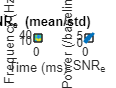

% snr
snr_bs = zeros(length(frequencies),EEG.pnts);
snr_tf = zeros(length(frequencies),EEG.pnts);
tf     = zeros(length(frequencies),EEG.pnts);

for fi=1:length(frequencies)
    
    % create wavelet and get its FFT
    wavelet = exp(2*1i*pi*frequencies(fi).*time) .* exp(-time.^2./(2*( wavelet_cycles /(2*pi*frequencies(fi)))^2))/frequencies(fi);
    fft_wavelet = fft(wavelet,n_conv_pow2);
    
    % run convolution
    convolution_result = ifft(fft_wavelet.*fft_data,n_conv_pow2) * sqrt(wavelet_cycles /(2*pi*frequencies(fi)));
    convolution_result = convolution_result(1:n_convolution);
    convolution_result = convolution_result(half_of_wavelet_size+1:end-half_of_wavelet_size);
    convolution_result = reshape(convolution_result,EEG.pnts,EEG.trials);
    
    % extract SNR in two ways
    snr_tf(fi,:) = mean(abs(convolution_result).^2,2)./std(abs(convolution_result).^2,[],2);
    snr_bs(fi,:) = mean(abs(convolution_result).^2,2)./std(mean(abs(convolution_result(baselineidx(1):baselineidx(2),:)).^2,1),[],2);
    
    % and extract trial-averaged power
    tf(fi,:) = mean(abs(convolution_result).^2,2);
    
end

% plot
figure
subplot(121)
contourf(EEG.times,frequencies,snr_bs,40,'linecolor','none')
set(gca,'clim',[.5 2],'xlim',[-200 1000],'ylim',[frequencies(1) 40])
% colorbar
title('SNR_b_a_s_e_l_i_n_e (mean/std)'), ylabel('Frequency (Hz)'), xlabel('Time (ms)')
axis square


subplot(122)
baseline_power = mean(tf(:,baselineidx(1):baselineidx(2)),2);
baselinediv    = tf ./ repmat(baseline_power,1,EEG.pnts);

plot(snr_bs(1:3:end),baselinediv(1:3:end),'.')
xlabel('SNR_b_a_s_e_l_i_n_e'), ylabel('Power (/baseline)')
axis square

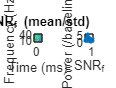



figure
subplot(121)
contourf(EEG.times,frequencies,snr_tf,40,'linecolor','none')
set(gca,'clim',[.5 1.25],'xlim',[-200 1000],'ylim',[frequencies(1) 40])
% colorbar
title('SNR_t_f (mean/std)'), ylabel('Frequency (Hz)'), xlabel('Time (ms)')
axis square

subplot(122)
plot(snr_tf(1:3:end),baselinediv(1:3:end),'.')
xlabel('SNR_t_f'), ylabel('Power (/baseline)')
axis square

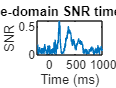


% time-series of SNR
figure
plot(EEG.times,abs(mean(EEG.data(47,:,:),3) ./ std(EEG.data(47,:,:),[],3)))
title('Time-domain SNR time series')
set(gca,'xlim',[-200 1000])
xlabel('Time (ms)'), ylabel('SNR')


% now compute SNR of peak compared to prestim noise
stimeidx = dsearchn(EEG.times',150);
etimeidx = dsearchn(EEG.times',400);
% disp([ 'ERP SNR between 150 and 400 ms at FCz: ' num2str(max(mean(EEG.data(47,stimeidx:etimeidx,:),3)) / std(mean(EEG.data(47,baselineidx(1):baselineidx(2),:),3),[],2)) ])


### **Number of Trials and Power Estimates**  

One way to test whether you have enough trials is by estimating the reliability of the trial-averaged power using random subsets of trials. 

The idea is the following. If there is no noise in the data, the time course of frequency-band-specific power on one trial will correlate perfectly with the time course of frequency-band-specific power averaged over all trials.  As noise increases, the correlation between an individual trial time course and the trial-average time course will decrease.

To determine whether, for example, 10 trials provide sufficient reliability, the power time course averaged over 10 randomly selected trials can be correlated with the power time course averaged over all trials. This procedure can be repeated for any number of trials between one and the total number of trials. When this analysis is repeated over frequencies, the result is a frequency-by-trial-count map of correlation coefficients. This entire procedure can be repeated over several iterations in order to select different random subsets of trials.   

iterations=10;
chan2plot = 'P7'; % or FCz
dbcorrect = false;

powerByTrialFreq = zeros(length(frequencies),EEG.trials);

start_time = -200; % in ms
end_time   = 1200;

fft_data = fft(reshape(EEG.data(strcmpi(chan2plot,{EEG.chanlocs.labels}),:,:),1,[]),n_conv_pow2);
timeidx = dsearchn(EEG.times',[start_time end_time]');

for fi=1:length(frequencies)
    
    % create wavelet and get its FFT
    wavelet = exp(2*1i*pi*frequencies(fi).*time) .* exp(-time.^2./(2*( wavelet_cycles /(2*pi*frequencies(fi)))^2))/frequencies(fi);
    fft_wavelet = fft(wavelet,n_conv_pow2);
    
    % run convolution
    convolution_result = ifft(fft_wavelet.*fft_data,n_conv_pow2) * sqrt(wavelet_cycles /(2*pi*frequencies(fi)));
    convolution_result = convolution_result(1:n_convolution);
    convolution_result = convolution_result(half_of_wavelet_size+1:end-half_of_wavelet_size);
    convolution_result = abs(reshape(convolution_result,EEG.pnts,EEG.trials)).^2; % reshape and convert to power
    
    % "gold standard" is average of all trials
    if dbcorrect
        template = 10*log10( bsxfun(@rdivide,mean(convolution_result,2),mean(mean(convolution_result(baselineidx(1):baselineidx(2),:),1),2)));
        template = template(timeidx(1):timeidx(2));
    else
        template = mean(convolution_result(timeidx(1):timeidx(2),:),2);
    end
    % normalize template for correlation
    template = bsxfun(@rdivide,bsxfun(@minus,template,mean(template)),std(template))';
    
    for iteri=1:iterations
        for triali=5:EEG.trials % start at 5 trials...
            
            trials2use = randsample(1:EEG.trials,triali);
            % if you don't have the stats toolbox, use the following:
            % trials2use = randperm(EEG.trials); trials2use = trials2use(1:triali);
            
            % compute power time series from the random selection of trials, and then normalization
            if dbcorrect
                tempdat = 10*log10( bsxfun(@rdivide,mean(convolution_result(:,trials2use),2),mean(mean(convolution_result(baselineidx(1):baselineidx(2),trials2use),1),2)));
                tempdat = tempdat(timeidx(1):timeidx(2));
            else
                tempdat = mean(convolution_result(timeidx(1):timeidx(2),trials2use),2);
            end
            tempdat = bsxfun(@rdivide,bsxfun(@minus,tempdat,mean(tempdat)),std(tempdat))';
            
            % compute Pearson correlation. This is a super-fast
            % implementation of a Pearson correlation via least squares
            % fit. You'll learn more about this in Chapter 28. 
            powerByTrialFreq(fi,triali) = powerByTrialFreq(fi,triali) + (tempdat*tempdat')\tempdat*template';
        end
    end
end

powerByTrialFreq = powerByTrialFreq./iterations;


figure
plot(5:EEG.trials,squeeze(powerByTrialFreq(:,5:end)))
xlabel('Number of trials'), ylabel('Power')
set(gca,'ylim',[-.1 1.1])
title('Each line is a frequency band')

figure
contourf(5:EEG.trials,frequencies,squeeze(powerByTrialFreq(:,5:end)),40,'linecolor','none')
set(gca,'clim',[.6 1])
xlabel('Number of trials'), ylabel('Frequency (Hz)')
if dbcorrect, title('DB normalized'), else title('not dB normalized'); end


Based on other measures of reliability (such as Cronbach’s *α*, for example), trial counts that correspond to correlations of around 0.7 should provide a reasonable number of trials per condition. For example, based on the results presented, around 50 trials seems to be a reasonable minimum number of trials.

**Exercises**

1. Select three frequency bands and compute time-varying power at each electrode in these three bands, using either complex wavelet convolution or filter-Hilbert. Compute and store both the baseline-corrected power and the raw non-baseline-corrected power. You can choose which time period and baseline normalization method to use.

2. Select five time points and create topographical maps of power with and without baseline normalization at each selected time-frequency point. You should have time in columns and  with/without baseline normalization in rows. Use separate figures for each frequency. The color scaling should be the same for all plots over time within a frequency, but the color scaling should be different for with versus without baseline normalization and should also be different for each frequency.

3. Are there qualitative differences in the topographical distributions of power with compared to without baseline normalization? Are the differences more prominent in some frequency bands or at some time points? What might be causing these differences?  